clc
clear
close all

Basic first order response plot

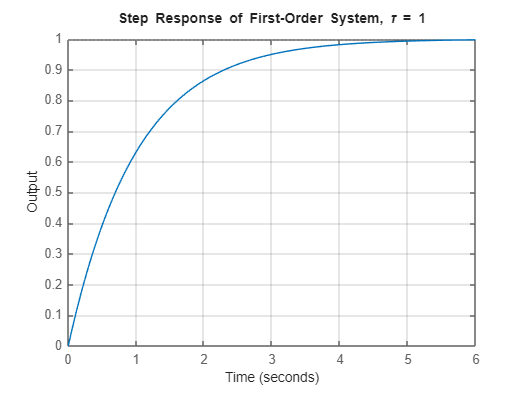

tau = 1;    % Time constant

% Define transfer function
gain = 1;   % TF gain
char_eqn = [1, tau];    % Characteristic equation
sys = tf(gain, char_eqn);

% Plot step response
figure;
step(sys);
title(['Step Response of First-Order System, \tau = ' num2str(tau)]);
xlabel('Time');
ylabel('Output');
grid on;

Examining behavior of changing time constant

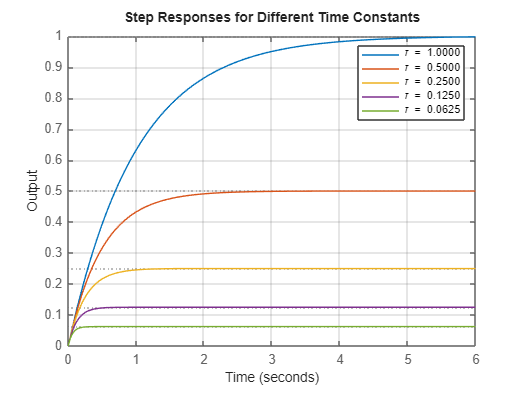

tau = [1 0.5 0.25 0.125 0.0625];
figure;

legendEntries = cell(1, length(tau));

for i = 1:length(tau)
    gain = 1;
    char_eqn = [1, 1/tau(i)];
    sys = tf(gain, char_eqn);
    step(sys);
    hold on;
    legendEntries{i} = sprintf('\\tau = %.4f', tau(i));
end

title('Step Responses for Different Time Constants');
xlabel('Time');
ylabel('Output');
grid on;
legend(legendEntries);
hold off;

Visualizing changes in gain

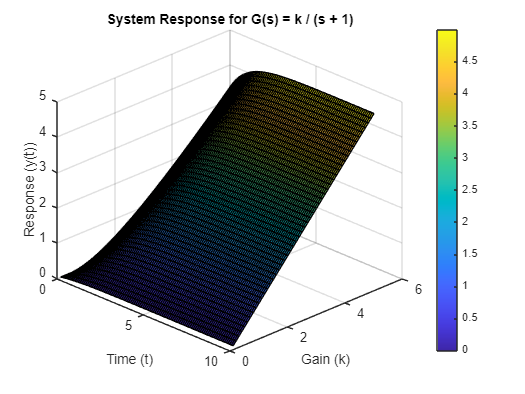

% Time vector for the response (e.g., from 0 to 10 seconds)
t = linspace(0, 10, 100);  % Time from 0 to 10 seconds, with 100 points

% Values of k (gain) from 0.1 to 5
k_values = linspace(0.1, 5, 50);  % 50 points for k

% Create meshgrid for time (t) and k (gain)
[K, T] = meshgrid(k_values, t);  % K corresponds to k values, T corresponds to time

% Calculate the system response for each combination of time and k
Y = K .* (1 - exp(-T));  % Response y(t) = k * (1 - exp(-t))

% Create the 3D surface plot
figure;
surf(T, K, Y);

% Customize the plot
xlabel('Time (t)');        % Label for x-axis (time)
ylabel('Gain (k)');        % Label for z-axis (k values)
zlabel('Response (y(t))'); % Label for y-axis (system response)
title('System Response for G(s) = k / (s + 1)'); % Title
colorbar;                  % Add a color bar to indicate response values

% Optional: Set view angle
view(45, 30);  % Adjust the viewpoint for better visualization